load flip_eqns.mat
load contact_eqns.mat
load roll_eqns.mat
syms rw r2 r3 r5 l7_ab I7 m1 m2 m3 m4 m5 m6 m7 I1 I2 I3 I4 I5 I6 g2 C_friction7 ta13 a51 tv13 t13 T_z s_contact1 s_contact2 ta23 tv23 t23 t1 t2 t3 t4 t5 t6
syms rw r2 r3 r5 l7_ab I7 m1 m2 m3 m4 m5 m6 m7 I1 I2 I3 I4 I5 I6 g2 C_friction7 ta13 a51 tv13 t13 T_z height1 length1 wheel_density frame_density gear_density gear_thickness frame_thickness wheel_thickness


design_parameters = [rw==0.075;
    r2==0.085/2;
    r3==0.055/2;
    r5==0.027/2;
    l7_ab==0.4;
    I7== 2;
    m7==0.5;
    C_friction7==0.1;
    gear_thickness==0.06;
    frame_thickness == 0.06;
    wheel_thickness == 0.06;
    gear_density== 1180; % kg/m^3 perspex
    frame_density== 1180; % kg/m^3 perspex
    wheel_density== 800; % kg/m^3 hardboard
    ];

derived_parameters = [
    length1==4*r5+4*r3+2*r2;
    height1==2*r2;
    m1==0.2*length1*height1*frame_thickness*frame_density;
    I1==m1/12*(length1.^2*height1.^2);
    m2==0.3*pi*r2.^2*gear_thickness*gear_density;
    m3==0.3*pi*r3.^2*gear_thickness*gear_density;
    m4==0.3*pi*r3.^2*gear_thickness*gear_density;
    m5==0.5*pi*r5.^2*gear_thickness*gear_density + 0.2*pi*rw.^2*wheel_thickness*wheel_density;
    m6==0.5*pi*r5.^2*gear_thickness*gear_density + 0.2*pi*rw.^2*wheel_thickness*wheel_density;
    I2==1/2*m2*r2.^2;
    I3==1/2*m3*r3.^2;
    I4==1/2*m4*r3.^2;
    I5==1/2*pi*r5.^4*gear_thickness*gear_density + 1/2*pi*rw.^4*wheel_thickness*wheel_density;
    I6==1/2*pi*r5.^4*gear_thickness*gear_density + 1/2*pi*rw.^4*wheel_thickness*wheel_density;
    g2==9.81;
    ];
derived_parameters = lhs(derived_parameters) == subs(rhs(derived_parameters), lhs(derived_parameters), rhs(derived_parameters));
derived_parameters = lhs(derived_parameters) == subs(rhs(derived_parameters), lhs(derived_parameters), rhs(derived_parameters));
derived_parameters = lhs(derived_parameters) == subs(rhs(derived_parameters), lhs(design_parameters), rhs(design_parameters));
design_parameters= [design_parameters; derived_parameters];


solve([design_parameters; derived_parameters], [m1, m2, m3, m4, m5, m6, m7])

ans = struct with fields:
    m1: [0×1 sym]
    m2: [0×1 sym]
    m3: [0×1 sym]
    m4: [0×1 sym]
    m5: [0×1 sym]
    m6: [0×1 sym]
    m7: [0×1 sym]


double(rhs(derived_parameters))

ans =     0.2490
    0.0850
    0.2997
    0.0000
    0.1205
    0.0505
    0.0505
    0.1899
    0.1899
    0.0001




step_height = 0.15;
rw_sim = 0.075;
rectangle_width = 0.085;


%apply to eqs
Q_eqn1=subs(flip_eqns, lhs(design_parameters), rhs(design_parameters));
%Q_eqn1= ta13 == simplify(rhs(Q_eqn1));

Q_eqn2=subs(contact_eqns, lhs(design_parameters), rhs(design_parameters));
%Q_eqn2= Q_eqn2(1);

Q_eqn3=subs(roll_eqns, lhs(design_parameters), rhs(design_parameters));
%Q_eqn3= Q_eqn3(1);

%Assign torque
Torque = 20; %Nm
Q_eqn1=subs(Q_eqn1, T_z, Torque);
%Q_eqn1= ta13 == simplify(rhs(Q_eqn1));

Q_eqn2=subs(Q_eqn2, T_z, Torque);
Q_eqn3=subs(Q_eqn3, T_z, Torque);
%Q_eqn2= ta13 == simplify(rhs(Q_eqn2))
%R_eqn=subs(roll_eqns, lhs(design_parameters), rhs(design_parameters))
%R_eqn= lhs(R_eqn) == simplify(rhs(R_eqn))

%Calculate threshold
contact_threshold = pi-atan((step_height-rw_sim)/rw_sim)-asin(rectangle_width/(2*sqrt((step_height-rw_sim).^2+rw_sim.^2)));
contact_point = [r2+2*r3+r5-sqrt((step_height-rw_sim).^2+rw_sim.^2-(rectangle_width/2).^2); rectangle_width/2];
hyp=contact_point+[r2+2*r3+r5;0]

$$hyp = \left(\begin{array}{c} 2\,r_{2}+4\,r_{3}+2\,r_{5}-\frac{7002481949836663}{72057594037927936}\\ \frac{17}{400} \end{array}\right)$$

hyp=sqrt(hyp(1).^2+hyp(2).^2)

$$hyp = \sqrt{{\left(2\,r_{2}+4\,r_{3}+2\,r_{5}-\frac{7002481949836663}{72057594037927936}\right)}^{2}+\frac{289}{160000}}$$

wheel_threshold = pi/2+asin(rectangle_width/(2*hyp))+acos(rw_sim/hyp)

$$wheel\_threshold = \frac{\pi }{2}+\mathrm{acos}\left(\frac{3}{40\,\sqrt{{\left(2\,r_{2}+4\,r_{3}+2\,r_{5}-\frac{7002481949836663}{72057594037927936}\right)}^{2}+\frac{289}{160000}}}\right)+\mathrm{asin}\left(\frac{17}{400\,\sqrt{{\left(2\,r_{2}+4\,r_{3}+2\,r_{5}-\frac{7002481949836663}{72057594037927936}\right)}^{2}+\frac{289}{160000}}}\right)$$

wheel_threshold= double(subs(wheel_threshold,lhs(design_parameters), rhs(design_parameters)));
landing_pos = sqrt(hyp.^2-rw_sim.^2)

$$landing\_pos = \sqrt{{\left(2\,r_{2}+4\,r_{3}+2\,r_{5}-\frac{7002481949836663}{72057594037927936}\right)}^{2}-\frac{611}{160000}}$$

syms u [4 1]
syms rk_eq1(u)
syms rk_eq2(u)


f= rhs(subs(Q_eqn1,[t13, tv13, t23, tv23], [u1, u2, u3, u4]));

rk_eq1(u1, u2, u3, u4) = [u2;f(1);u4;f(2)];

f= rhs(subs(Q_eqn2,[t13, tv13, t23, tv23], [u1, u2, u3, u4]));
f= subs(f,[s_contact1; s_contact2], contact_point);
f= subs(f,lhs(design_parameters), rhs(design_parameters));
rk_eq2(u1, u2, u3, u4) = [u2;f(1);u4;f(2)];

f= rhs(subs(Q_eqn3,[t13, tv13, t23, tv23], [u1-pi, u2, u3, u4]));

rk_eq3(u1, u2, u3, u4) = [u2;f(1);u4;f(2)];



Step_Value = 0.01;
t_beg = 0;
t_end = 1;
t_intial=0;
u_intial=[0,0,0,0];
% Routine starts here
h=Step_Value;
t=t_beg:h:t_end;
u=zeros(4,length(t));
u(:,1)=u_intial;
contact_time=length(t)+1

contact_time = 102

wheel_time= length(t)+1

wheel_time = 102


stage=1;

for i=1:(length(t)-1)
    t0=t(i);
    up1=u(1,i);
    up2=u(2,i);
    up3=u(3,i);
    up4=u(4,i);
    if stage == 1
        k1 = double(rk_eq1(up1, up2, up3, up4));
        k2 = double(rk_eq1(up1+0.5*h*k1(1), up2+0.5*h*k1(2), up3+0.5*h*k1(3),up4+0.5*h*k1(4)));
        k3 = double(rk_eq1(up1+0.5*h*k2(1), up2+0.5*h*k2(2), up3+0.5*h*k2(3),up4+0.5*h*k2(4)));
        k4 = double(rk_eq1(up1+k3(1)*h, up2+k3(2)*h, up3+k3(3)*h, up4+k3(4)*h));
        u(:,i+1) = u(:,i) + (h/6)*(k1+2*k2+2*k3+k4);
        if u(1,i) >= contact_threshold
            stage = 2;
            contact_time = i
        end
    
    elseif stage == 2
        k1 = double(rk_eq2(up1, up2, up3, up4));
        k2 = double(rk_eq2(up1+0.5*h*k1(1), up2+0.5*h*k1(2), up3+0.5*h*k1(3),up4+0.5*h*k1(4)));
        k3 = double(rk_eq2(up1+0.5*h*k2(1), up2+0.5*h*k2(2), up3+0.5*h*k2(3),up4+0.5*h*k2(4)));
        k4 = double(rk_eq2(up1+k3(1)*h, up2+k3(2)*h, up3+k3(3)*h, up4+k3(4)*h));
        u(:,i+1) = u(:,i) + (h/6)*(k1+2*k2+2*k3+k4);
        if u(1,i) >= wheel_threshold
            stage = 3;
            wheel_time = i
        end
    elseif stage == 3
        k1 = double(rk_eq3(up1, up2, up3, up4));
        k2 = double(rk_eq3(up1+0.5*h*k1(1), up2+0.5*h*k1(2), up3+0.5*h*k1(3),up4+0.5*h*k1(4)));
        k3 = double(rk_eq3(up1+0.5*h*k2(1), up2+0.5*h*k2(2), up3+0.5*h*k2(3),up4+0.5*h*k2(4)));
        k4 = double(rk_eq3(up1+k3(1)*h, up2+k3(2)*h, up3+k3(3)*h, up4+k3(4)*h));
        u(:,i+1) = u(:,i) + (h/6)*(k1+2*k2+2*k3+k4);
        i
    end
end
u

u =          0   -0.0002   -0.0009   -0.0020   -0.0035   -0.0055   -0.0080   -0.0108   -0.0141   -0.0179   -0.0221   -0.0267   -0.0318   -0.0374   -0.0433   -0.0497   -0.0566   -0.0639   -0.0716   -0.0798   -0.0884   -0.0974   -0.1069   -0.1168   -0.1271   -0.1379   -0.1491   -0.1607   -0.1728   -0.1852   -0.1981   -0.2114   -0.2251   -0.2392   -0.2537   -0.2686   -0.2839   -0.2996   -0.3156   -0.3320   -0.3488   -0.3659   -0.3833   -0.4011   -0.4192   -0.4376   -0.4563   -0.4753   -0.4946   -0.5141
         0   -0.0442   -0.0884   -0.1326   -0.1768   -0.2210   -0.2652   -0.3095   -0.3537   -0.3979   -0.4420   -0.4862   -0.5304   -0.5745   -0.6186   -0.6627   -0.7067   -0.7507   -0.7946   -0.8384   -0.8821   -0.9257   -0.9692   -1.0125   -1.0556   -1.0985   -1.1412   -1.1836   -1.2257   -1.2675   -1.3089   -1.3499   -1.3905   -1.4306   -1.4702   -1.5092   -1.5475   -1.5852   -1.6222   -1.6583   -1.6937   -1.7282   -1.7617   -1.7942   -1.8257   -1.8560   -1.8852   -1.9132   -1.9399   -1

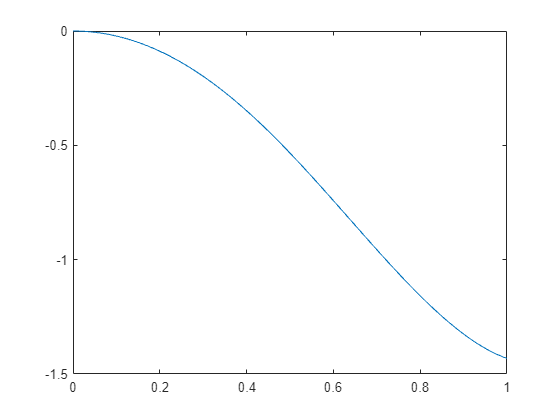


plot(t,u(1,:))


%pre contact
s5(t13)=[0, rw];
s2(t13)=s5 + (r5+2*r3+r2)*[-cos(t13), sin(t13)];
s6(t13)=s5 + 2*(r5+2*r3+r2)*[-cos(t13), sin(t13)];
s2(t13)=subs(s2,lhs(design_parameters), rhs(design_parameters));
s5(t13)=subs(s5,lhs(design_parameters), rhs(design_parameters));
s6(t13)=subs(s6,lhs(design_parameters), rhs(design_parameters));

%post contact

Rz = [cos(t13), sin(t13), 0;
    -sin(t13), cos(t13), 0;
    0, 0, 1];


eq=-Rz*[contact_point;0];
s22(t13)=eq(1:2).';
s22(t13)=s22(t13)+[rw_sim, step_height];
s52(t13)=s22 - (r5+2*r3+r2)*[-cos(t13), sin(t13)];
s62(t13)=s22 + (r5+2*r3+r2)*[-cos(t13), sin(t13)];
s22(t13)=subs(s22,lhs(design_parameters), rhs(design_parameters));
s52(t13)=subs(s52,lhs(design_parameters), rhs(design_parameters));
s62(t13)=subs(s62,lhs(design_parameters), rhs(design_parameters));





t_eqns = [t3-t1 == -r2/r3*(t2-t1);
    t4-t1 == -r2/r3*(t2-t1);
    t5-t1 == -r3/r5*(t3-t1);
    t6-t1 == -r3/r5*(t4-t1);
    ];
t_eqns(1)=isolate(t_eqns(1),t3);
t_eqns(2)=isolate(t_eqns(2),t4);
t_eqns(3)=isolate(t_eqns(3),t5);
t_eqns(4)=isolate(t_eqns(4),t6);

t_eqns(3)=subs(t_eqns(3),lhs(t_eqns(1)), rhs(t_eqns(1)));
t_eqns(4)=subs(t_eqns(4),lhs(t_eqns(2)), rhs(t_eqns(2)));

theta5(t1,t2)=rhs(t_eqns(3));
theta6(t1,t2)=rhs(t_eqns(4));
theta5(t1,t2)=subs(theta5(t1,t2),lhs(design_parameters), rhs(design_parameters));
theta6(t1,t2)=subs(theta6(t1,t2),lhs(design_parameters), rhs(design_parameters));

s63(t1, t2)=[rw*t6+landing_pos+rw_sim, rw+step_height];
s63(t1, t2)=subs(s63(t1, t2),lhs(t_eqns(4)), rhs(t_eqns(4)));

s23(t1, t2)=s63(t1, t2) - (r5+2*r3+r2)*[-cos(t1), sin(t1)];
s53(t1, t2)=s63(t1, t2) - 2*(r5+2*r3+r2)*[-cos(t1), sin(t1)];
s23(t1, t2)=subs(s23,lhs(design_parameters), rhs(design_parameters));
s53(t1, t2)=subs(s53,lhs(design_parameters), rhs(design_parameters));
s63(t1, t2)=subs(s63,lhs(design_parameters), rhs(design_parameters));



p2=zeros(2,length(t));
p5=zeros(2,length(t));
p6=zeros(2,length(t));
thetas5=zeros(1,length(t));
thetas6=zeros(1,length(t));
tests=zeros(1,length(t));

for i=1:length(t)
    if i< contact_time
        p5(:,i)=double(s5(u(1,i)));
        p2(:,i)=double(s2(u(1,i)));
        p6(:,i)=double(s6(u(1,i)));
    elseif i< wheel_time
        p5(:,i)=double(s52(u(1,i)));
        p2(:,i)=double(s22(u(1,i)));
        p6(:,i)=double(s62(u(1,i)));
    else
        p5(:,i)=double(s53(u(1,i), u(3,i)));
        p2(:,i)=double(s23(u(1,i), u(3,i)));
        p6(:,i)=double(s63(u(1,i), u(3,i)));
    end
    thetas5(i)=double(theta5(u(1,i), u(3,i)));
    thetas6(i)=double(theta6(u(1,i), u(3,i)));
end
thetas5

thetas5 = 1.0e-14 *

         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0001   -0.0000   -0.0000   -0.0005   -0.0004   -0.0006   -0.0008   -0.0010   -0.0018   -0.0012   -0.0015   -0.0021   -0.0007   -0.0015   -0.0021   -0.0020   -0.0035   -0.0017   -0.0019    0.0015    0.0007    0.0021    0.0006    0.0039    0.0082    0.0076    0.0149    0.0130    0.0147    0.0078    0.0048    0.0121    0.0163    0.0154    0.0199    0.0191    0.0149    0.0138    0.0183    0.0152    0.0074    0.0014    0.0014    0.0088    0.0008


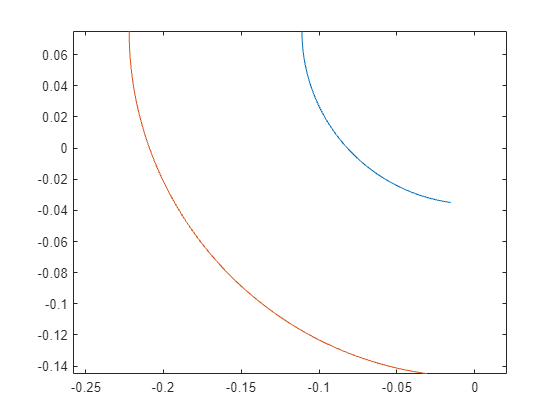


plot(p2(1,:), p2(2,:))
axis equal
hold on
plot(p6(1,:), p6(2,:))
hold off


F(length(t)) = struct('cdata',[],'colormap',[]);
for j=1:length(t)
    f=figure('visible','off');
    hold on;
    %wheels
    circle(p6(1,j), p6(2,j), rw_sim);
    line([p6(1,j),p6(1,j)+rw_sim*cos(thetas5(j))],[p6(2,j),p6(2,j)-rw_sim*sin(thetas5(j))])
    
    circle(p5(1,j), p5(2,j), rw_sim);
    line([p5(1,j),p5(1,j)+rw_sim*cos(thetas5(j))],[p5(2,j),p5(2,j)-rw_sim*sin(thetas5(j))])

    %frame
    corner(:,1) = [p6(1,j)+rectangle_width/2*sin(u(1,j)); p6(2,j)+rectangle_width/2*cos(u(1,j))];
    corner(:,2) = [p6(1,j)-rectangle_width/2*sin(u(1,j)); p6(2,j)-rectangle_width/2*cos(u(1,j))];
    corner(:,3) = [p5(1,j)-rectangle_width/2*sin(u(1,j)); p5(2,j)-rectangle_width/2*cos(u(1,j))];
    corner(:,4) = [p5(1,j)+rectangle_width/2*sin(u(1,j)); p5(2,j)+rectangle_width/2*cos(u(1,j))];
    corner(:,5) = corner(:,1);
    line(corner(1,:), corner(2,:))


    axis equal;
    xlim([-0.3,0.3])
    ylim([-0.1, 0.5])
    line([rw_sim, rw_sim], [0, step_height])
    line([rw_sim, 3], [step_height, step_height])
    hold off;
    F(j) = getframe(gcf);
end

fig = figure;



movie(fig, F, 1, 1/h);

function h = circle(x,y,r)
th = 0:pi/50:2*pi;
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
h = plot(xunit, yunit);
end